# Chapter 7 Part 2

# Amelia Rotondo - CWID: 887925113

## Question 6: 

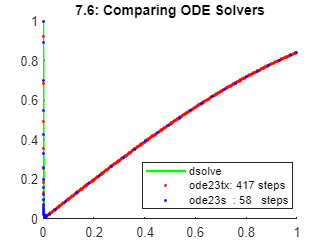

% Initialize the Problem
syms y(t) t;
odesym = diff(y,t) == -1000*(y-sin(t))+cos(t); 
odefun = @(t, y) -1000*(y - sin(t)) + cos(t);
y0 = 1; 
tspan = [0 1];

% Solution By dsolve: 
y_ds(t) = dsolve(odesym, y(0)==1);

% Solve using ode23s and ode23tx
[t_23, y_23] = ode23s(odefun, tspan, y0);
[t_tx, y_tx] = ode23tx(odefun, tspan, y0);
steps_23 = length(t_23);
steps_tx = length(t_tx);
label_23 = append('ode23s  : ',num2str(steps_23), '   steps');
label_tx = append('ode23tx: ',num2str(steps_tx), ' steps');

% Plot the Data
figure(1); clf; hold on; 
fplot(y_ds, [0, 1], 'g','DisplayName', 'dsolve', 'LineWidth',2);
plot(t_tx, y_tx, 'r.', 'DisplayName', label_tx, 'LineWidth',2);
plot(t_23, y_23, 'b.', 'DisplayName', label_23, 'LineWidth',2);
hold off; 
ttl = title('7.6: Comparing ODE Solvers');
lgd = legend('Location', 'best');

lgd; ttl;
fprintf('Number of Steps for ode23  : %d\n', length(t_23));

Number of Steps for ode23  : 58


fprintf('Number of Steps for ode23tx: %d\n', length(t_tx));

Number of Steps for ode23tx: 417


## Question 7: 

#### 
$$\dot{y} = cos(t), y(0) = 0\\
\dot{y} = \sqrt{1-y^2}, y= 0\\
\ddot{y} = -y, y(0) = 0, \dot{y} = 1\\
\ddot{y} = -sin(t), y(0) = 0, \dot{y} = 1\\$$


% Original Data 
y0_1 = 0; y0_2 = [0; 1];  
y_dot1  = @(y, t) cos(t);
y_dot2 = @(y, t) sqrt(1-y.^2); 
y_ddot1 = @(y, t) -y; 
y_ddot2 = @(y, t) -sin(t); 

#### a) Common Solution: 

% Common Solution 
syms y(t)

% First Equation
eq1 = diff(y, t) == cos(t);
cond1 = y(0) == 0;
sol1 = dsolve(eq1, cond1);

% Second Equation
eq2 = diff(y, t) == sqrt(1 - y^2);
cond2 = y(0) == 0;
sol2 = dsolve(eq2, cond2);

% Third Equation
eq3 = diff(y, t, t) == -y;
cond3 = [y(0) == 0, subs(diff(y, t), t, 0) == 1];
sol3 = dsolve(eq3, cond3);

% Fourth Equation 
eq4 = diff(y, t, t) == -sin(t);
cond4 = [y(0) == 0, subs(diff(y, t), t, 0) == 1];
sol4 = dsolve(eq4, cond4);

% Display the Common Solution
if (sol1 == sol2)&(sol1 == sol3)&(sol1 == sol4)
    disp('Solution:');
    disp(sol1);
end

Solution:


$$\sin\left(t\right)$$

#### b) Write Two Systems for the two 2nd Derivative Problems

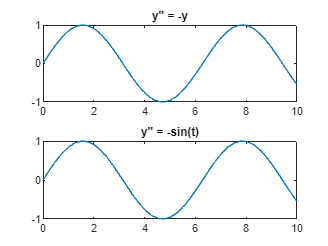

% First System: y'' = -y
sys1 = @(t, y) [y(2); -y(1)];
y0_sys1 = [0; 1];  

% Second System: y'' = -sin(t)
sys2 = @(t, y) [y(2); -sin(t)];
y0_sys2 = [0; 1];  

% Plot to Verify Solution:
tspan = [0, 10];
[t1, y1] = ode45(sys1, tspan, y0_sys1);
[t2, y2] = ode45(sys2, tspan, y0_sys2);
figure(3); clf; hold on; 
subplot(2,1,1);
plot(t1, y1(:,1));
title('y'''' = -y');
subplot(2,1,2);
plot(t2, y2(:,1));
title('y'''' = -sin(t)');
hold off; 

#### c) Write the Jacobian 


$$J = \frac{\partial f}{\partial y}$$



$$\begin{array}{rcl}
\dot{y} = cos(t) &\rightarrow& J = \frac{\partial}{\partial y} = 0\\
\dot{y} = \sqrt{1-t^2} &\rightarrow& J = \frac{\partial}{\partial y} = 0\\
\ddot{y} = -y &\rightarrow& J  =\left[\matrix{ 0 & 1 \cr -1 & 0} \right]\\
\ddot{y} = -sin(t) &\rightarrow& J  =\left[\matrix{ 0 & 1 \cr 0 & 0} \right]\\
\end{array}$$


#### d) Determine Steps for ode45 with AbsTol & RelTol = 1e-8

% Initializing Info:
tspan = [0, 10];
opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);

% ode45 Solutions:
[t1, y1] = ode45(y_dot1, tspan, y0_1, opts);
[t2, y2] = ode45(y_dot2, tspan, y0_1, opts);
[t3, y3] = ode45(@(t,y) [y(2); y_ddot1(t, y(1))], tspan, y0_2, opts);
[t4, y4] = ode45(@(t,y) [y(2); y_ddot2(t, y(1))], tspan, y0_2, opts);

% Amount of Iterations: 
[i1, ~] = size(t1);
[i2, ~] = size(t2);
[i3, ~] = size(t3);
[i4, ~] = size(t4);

% Display Results:
fprintf('Work for f1: %d Steps\n', i1);

Work for f1: 221 Steps


fprintf('Work for f2: %d Steps\n', i2);

Work for f2: 221 Steps


fprintf('Work for f3: %d Steps\n', i3);

Work for f3: 53 Steps


fprintf('Work for f4: %d Steps\n', i4);

Work for f4: 409 Steps


Some problems require more work than others because even though they all conclude at the same result, the method of writing the ode influences how many steps are needed to develop a correct approximation from the given ODE. While more fluid equations like sin and cos require more steps, simple equations like the harmonic equation are easier to approximate. 

#### e) Tspan = [0 pi]

% Initializing Info:
tspan = [0, pi];
opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);

% ode45 Solutions:
[t1, y1] = ode45(y_dot1, tspan, y0_1, opts);
[t2, y2] = ode45(y_dot2, tspan, y0_1, opts);
[t3, y3] = ode45(@(t,y) [y(2); y_ddot1(t, y(1))], tspan, y0_2, opts);
[t4, y4] = ode45(@(t,y) [y(2); y_ddot2(t, y(1))], tspan, y0_2, opts);

% Amount of Iterations: 
[i1, ~] = size(t1);
[i2, ~] = size(t2);
[i3, ~] = size(t3);
[i4, ~] = size(t4);

% Display Results:
fprintf('Work for f1: %d Steps\n', i1);

Work for f1: 109 Steps


fprintf('Work for f2: %d Steps\n', i2);

Work for f2: 189 Steps


fprintf('Work for f3: %d Steps\n', i3);

Work for f3: 49 Steps


fprintf('Work for f4: %d Steps\n', i4);

Work for f4: 129 Steps


Now for some reason, f4 is more efficient to calculate than f2. Additionally, f1 is more efficient to calculate than f2. This is most likely because the difference in bounds better represents the characteristics of sin and cos, therefore reducing the amount of work needed to appropriately approximate these values. 

#### f) f2 =$\dot{y} = \sqrt{|1-y^2|}, y(0) = 0$

% Change f2
y_dot2 = @(y, t) sqrt(abs(1-y.^2)); 

% Initializing Info:
tspan = [0, pi];
opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);

% ode45 Solutions:
[t1, y1] = ode45(y_dot1, tspan, y0_1, opts);
[t2, y2] = ode45(y_dot2, tspan, y0_1, opts);
[t3, y3] = ode45(@(t,y) [y(2); y_ddot1(t, y(1))], tspan, y0_2, opts);
[t4, y4] = ode45(@(t,y) [y(2); y_ddot2(t, y(1))], tspan, y0_2, opts);

% Amount of Iterations: 
[i1, ~] = size(t1);
[i2, ~] = size(t2);
[i3, ~] = size(t3);
[i4, ~] = size(t4);

% Display Results:
fprintf('Work for f1: %d Steps\n', i1);

Work for f1: 109 Steps


fprintf('Work for f2: %d Steps\n', i2);

Work for f2: 185 Steps


fprintf('Work for f3: %d Steps\n', i3);

Work for f3: 49 Steps


fprintf('Work for f4: %d Steps\n', i4);

Work for f4: 129 Steps


After changing to incoroporate the absolute value into our answer, it's clear that the new f2 takes 4 less steps to solve than the original f2. Therefore, it's safe to say that this change improved the approximation given, even if just by a slight margin. 

## Question 8:

#### Jacobian and Eig in Symbolic Toolbox to verify the two-body problem:

% Original Values
syms y1 y2 y3 y4 r;
r_fun = sqrt(y1^2 + y2^2);

% Find Two-Body Jacobian
f = [y3; y4; -y1/r_fun^3; -y2/r_fun^3];
v = [y1; y2; y3; y4];
J = simplify(jacobian(f, v));
J = subs(J, sqrt(y1^2 + y2^2), r);

% Find Eigenvalues of Jacobian
Jeig = simplify(eig(J));

% Display Results
Jeig = (r.^(3/2)).*Jeig;
J = (r.^5).*J;
disp('Jacobian J:');

Jacobian J:


disp(J);

$$\left(\begin{array}{cccc} 0 & 0 & r^{5} & 0\\ 0 & 0 & 0 & r^{5}\\ 2\,{y_{1}}^{2}-{y_{2}}^{2} & 3\,y_{1}\,y_{2} & 0 & 0\\ 3\,y_{1}\,y_{2} & 2\,{y_{2}}^{2}-{y_{1}}^{2} & 0 & 0 \end{array}\right)$$

disp('With Eigenvalues:');

With Eigenvalues:


disp(Jeig);

$$\begin{array}{l} \left(\begin{array}{c} \sigma_{2}\\ \sigma_{1}\\ -\sigma_{2}\\ -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,r^{13/2}\,\sqrt{\frac{{y_{1}}^{2}+{y_{2}}^{2}}{r^{15}}}\\ \sigma_{2}=r^{13/2}\,\sqrt{-\frac{{y_{1}}^{2}+{y_{2}}^{2}}{r^{15}}} \end{array}$$

**Note: **


$$r^{13/2} \sqrt{\frac{y_1^2+y_2^2}{r^{15}}}
= \sqrt{\frac{r^{13}(y_1^2+y_2^2)}{r^{15}}}
= \sqrt{\frac{(y_1^2+y_2^2)}{r^2}}}
$$



$$= \sqrt{\frac{(y_1^2+y_2^2)}{(y_1^2+y_2^2)}}} $$



$$= \sqrt{1} = 1$$


## Question 9:

#### Verify Null Vector and Singularity of Lorenz Equations: 

% Initial Values
syms beta sigma rho eta
L = [-beta, 0, eta; 0, -sigma, sigma; -eta, rho, -1];

% Determine Singularity 
detA = det(L);
eta_val = solve(detA == 0, eta);
disp('Solutions for eta:');

Solutions for eta:


disp(eta_val);

$$\left(\begin{array}{c} \sqrt{\beta }\,\sqrt{\rho -1}\\ -\sqrt{\beta }\,\sqrt{\rho -1} \end{array}\right)$$


% Find Null Vector
eta_sol = sqrt(beta * (rho - 1));
L = subs(L, eta, eta_sol);
L_null = eta_sol .* null(L);
disp('Null vectors:');

Null vectors:


disp(L_null);

$$\left(\begin{array}{c} \rho -1\\ \sqrt{\beta \,\left(\rho -1\right)}\\ \sqrt{\beta \,\left(\rho -1\right)} \end{array}\right)$$

## Question 10: 

#### Compute Jacobian and Eig for Lorenz Equations at a Fixed Point. Verify that the Fixed Point is Unstable. 

% Initial Values
syms sigma rho beta x y z
dxdt = sigma * (y - x);
dydt = x * (rho - z) - y;
dzdt = x * y - beta * z;

% Jacobian of Lorenz
F = [dxdt; dydt; dzdt];
v = [x; y; z];
J = jacobian(F, v);

% Identify Fixed Points
L_fixed = solve([dxdt == 0, dydt == 0, dzdt == 0], [x, y, z]);
fp_x = L_fixed.x(1);
fp_y = L_fixed.y(1);
fp_z = L_fixed.z(1);
fp = [fp_x; fp_y; fp_z];

% Find Eigenvalues at a fp (given fixed point)
J_fp = subs(J, v, fp);
eig_fp = simplify(eig(J_fp));

% Display results
disp('Eigenvalues at the fixed point (0,0,0):');

Eigenvalues at the fixed point (0,0,0):


disp(eig_fp);

$$\left(\begin{array}{c} -\beta \\ -\frac{\sigma }{2}-\frac{\sqrt{4\,\rho \,\sigma -2\,\sigma +\sigma^{2}+1}}{2}-\frac{1}{2}\\ \frac{\sqrt{4\,\rho \,\sigma -2\,\sigma +\sigma^{2}+1}}{2}-\frac{\sigma }{2}-\frac{1}{2} \end{array}\right)$$

For the Fixed Point to be stable, we would need to show that:


$$\beta < 0, \text{or}\\
-\frac{\sigma}{2} > -\frac{\sqrt{4\rho\sigma-2\sigma+\sigma^2+1}}{2} - \frac{1}{2} , \text{or}\\
\frac{\sqrt{4\rho\sigma-2\sigma+\sigma^2+1}}{2} > -\frac{\sigma}{2} - \frac{1}{2} \\$$


Therefore, we can assume that the system is unstable at this fixed point.

## Question 11: 

#### Find largest rho such that Lorenz Equation Fixed Points are Stable

% Sample Parameters for Sigma and Beta
sigma = 200;  
beta = 8/3;  

% Initialize rho
rho = 0;
max_rho = 100; 
step_size = 0.01;  

% Find the Max Rho for Stability
while rho < max_rho
    eigenval1 = -beta;
    eigenval2 = -sigma/2 - sqrt(4*rho*sigma - 2*sigma + sigma^2 + 1)/2 - 1/2;
    eigenval3 = sqrt(4*rho*sigma - 2*sigma + sigma^2 + 1)/2 - sigma/2 - 1/2;
    if real(eigenval2) > 0 || real(eigenval3) > 0
        break;
    end
    
    % Increment rho
    rho = rho + step_size;
end

% The last stable value of rho
rho_stable = rho - step_size;

% Display the result
disp(['Maximum value of Rho for stability: ', num2str(rho_stable)]);

Maximum value of rho for stability: 1


## Question 12: 

#### lorenzgui with rho = 28